robot = rigidBodyTree('DataFormat','column','MaxNumBodies',3);

L1 = 0.3;
L2 = 0.3;

body = rigidBody('link1');
joint = rigidBodyJoint('joint1', 'revolute');
setFixedTransform(joint,trvec2tform([0 0 0]));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'base');

body = rigidBody('link2');
joint = rigidBodyJoint('joint2','revolute');
setFixedTransform(joint, trvec2tform([L1,0,0]));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link1');

body = rigidBody('tool');
joint = rigidBodyJoint('fix1','fixed');
setFixedTransform(joint, trvec2tform([L2, 0, 0]));
body.Joint = joint;
addBody(robot, body, 'link2');

showdetails(robot)

--------------------
Robot: (3 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        link1        joint1      revolute             base(0)   link2(2)  
   2        link2        joint2      revolute            link1(1)   tool(3)  
   3         tool          fix1         fixed            link2(2)   
--------------------


t = (0:0.2:10)'; % Time
count = length(t);
center = [0.3 0.1 0];
radius = 0.15;
theta = t*(2*pi/t(end));
points = center + radius*[cos(theta) sin(theta) zeros(size(theta))];

q0 = homeConfiguration(robot);
ndof = length(q0);
qs = zeros(count, ndof);

ik = inverseKinematics('RigidBodyTree', robot);
weights = [0, 0, 0, 1, 1, 0];
endEffector = 'tool';

qInitial = q0; % Use home configuration as the initial guess
for i = 1:count
    % Solve for the configuration satisfying the desired end effector
    % position
    point = points(i,:);
    qSol = ik(endEffector,trvec2tform(point),weights,qInitial);
    % Store the configuration
    qs(i,:) = qSol;
    % Start from prior solution
    qInitial = qSol;
end

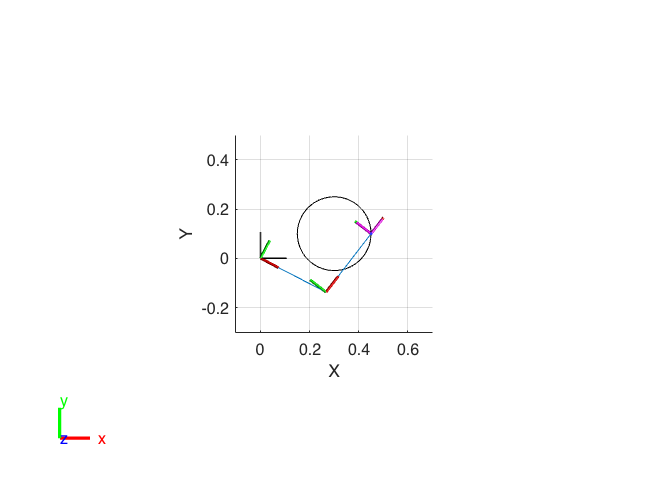

figure
show(robot,qs(1,:)');
view(2)
ax = gca;
ax.Projection = 'orthographic';
hold on
plot(points(:,1),points(:,2),'k')
axis([-0.1 0.7 -0.3 0.5])

framesPerSecond = 5;
r = rateControl(framesPerSecond);
for i = 1:count
    show(robot,qs(i,:)','PreservePlot',false);
    drawnow
    waitfor(r);
end